**Exercise 1**

Implement the Forward Euler method in a function.

Test it on $\frac{dx}{dt} = -0.5 x$ with $x(0) = 1$ for $0 \leq t \leq 20$.

Try using $h = 1$, $h = 3$, and $h = 4.2$ to provoke instability. Compare against the analytical solution $x(t) = e^{-0.5t}$.

clear; close all; clc;

function x = odeFE(f, x0, t)
% solves an ordinary differential equation using the Forward Euler method.
%
% Inputs: f    Function handle for evaluating the ODE
%         x0   Initial condition
%         t    Time vector [t_0 t_1 t_2 ... t_n]
% Output: x    Resulting function values at each time step in t
    n = length(t);      %number of time points

    x = zeros(n,1);
    x(1) = x0;          %initial condition

    for k = 1:n-1
        h = t(k+1) - t(k);
        x(k+1) = x(k) + h*f(t(k),x(k)); % Forward Euler step
    end
end

Tests:

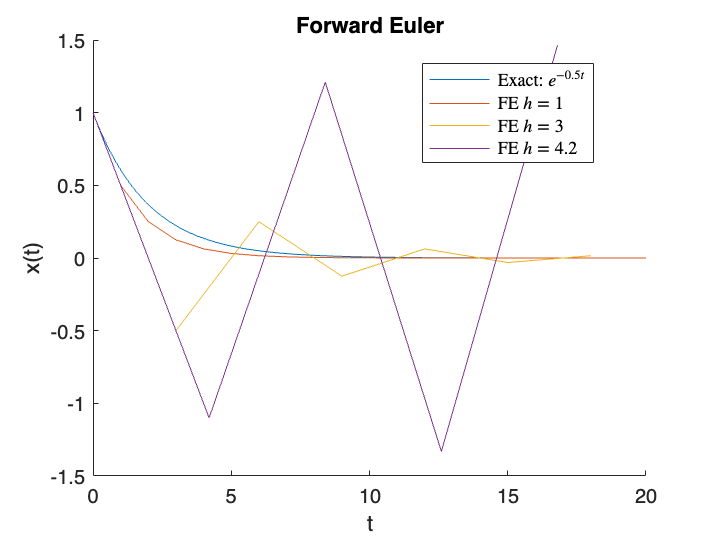

%ODE: dx/dt = -0.5 x
f  = @(t,x) -0.5*x;
x0 = 1;
t0 = 0; 
tEnd = 20;

hValues = [1, 3, 4.2];

figure;
hold on;

tFine = linspace(t0, tEnd, 1000);
plot(tFine, exp(-0.5*tFine));

%Forward Euler for each h
for h = hValues
    t = t0:h:tEnd;
    
    x = odeFE(f, x0, t);
    plot(t, x);
end

legend("Exact: $e^{-0.5t}$", "FE $h = 1$", "FE $h = 3$", "FE $h = 4.2$", "Location", "best", "interpreter", "latex");
xlabel("t");
ylabel("x(t)");
title("Forward Euler");
hold off;

**Exercise 2**

Write a Matlab function that gets any arbitrary function $f(x,t), x_0,$ and $t$ as the inputs and solves the first order ODE


$$\dot{x} = f(x,t)$$


- using Newton-Raphson in each time step and

- approximating the derivative by a finite difference

Test it on $\frac{dx}{dt} = 0.5x$ with $x(0) = 1$ for $0 \leq t \leq 20$ again.

Try using $h = 1$, $h = 3$, and $h = 4.2$ to see if it is stable.

function x = odeBE(f, x0, t)
% solves an ordinary differential equation using the Backward Euler method.
%
% Inputs: f    Function handle for evaluating the ODE
%         x0   Initial condition
%         t    Time vector [t_0 t_1 t_2 ... t_n]
% Output: x    Resulting function values at each time step in t
    tol = 1e-10;

    n = length(t);      %number of time points

    x = zeros(n,1);
    x(1) = x0;          %initial condition

    for k = 1:n-1
        h = t(k+1) - t(k);

        % Backward Euler step:
        % x(k+1) = x(k) + h * f(t(k+1), x(k+1))

        z = x(k);       %initial guess for x(k+1)

        for it = 1:50   %Newton iterations
            %g(z) = z - x(k) - h*f(t(k+1), z)  (should be 0)
            g = z - x(k) - h*f(t(k+1), z);

            %g'(z) found with finite difference
            eps = 1e-6*(1 + abs(z));
            g_eps = (z+eps) - x(k) - h*f(t(k+1), z+eps);
            gp = (g_eps - g) / eps;

            z_new = z - g/gp;

            if abs(z_new - z) < tol
                z = z_new;
                break;
            end

            z = z_new;
        end

        x(k+1) = z;
    end
end

Tests:

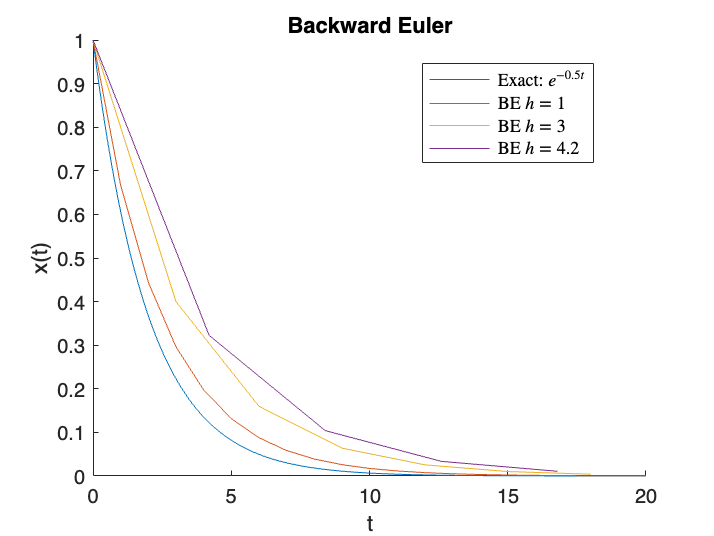

% ODE: dx/dt = -0.5 x
f  = @(t,x) -0.5*x;
x0 = 1;
t0 = 0; 
tEnd = 20;

hValues = [1, 3, 4.2];

figure;
hold on;

tFine = linspace(t0, tEnd, 1000);
plot(tFine, exp(-0.5*tFine));

%Backward Euler for each h
for h = hValues
    t = t0:h:tEnd;
    
    x = odeBE(f, x0, t);
    plot(t, x);
end

legend("Exact: $e^{-0.5t}$", "BE $h = 1$", "BE $h = 3$", "BE $h = 4.2$", "Location", "best", "interpreter", "latex");
xlabel("t");
ylabel("x(t)");
title("Backward Euler");
hold off;

**Exercise 3**

Try to modify your code for Exercise 2 to solve the same ODE by the Trapezoidal Method.

Test it on $\frac{dx}{dt} = 0.5x$ with $x(0) = 1$ for $0 \leq t \leq 20$ again.

Try using $h = 1$, $h = 3$, and $h = 4.2$ to see if it is stable.

function x = odeTrapezoid(f, x0, t)
% solves an ordinary differential equation using the Trapezoidal method.
%
% Inputs: f    Function handle for evaluating the ODE
%         x0   Initial condition
%         t    Time vector [t_0 t_1 t_2 ... t_n]
% Output: x    Resulting function values at each time step in t

    tol = 1e-10;

    n = length(t);      %number of time points

    x = zeros(n,1);
    x(1) = x0;          %initial condition

    for k = 1:n-1
        h = t(k+1) - t(k);

        % Trapezoidal step:
        % x(k+1) = x(k) + (h/2)*( f(t(k),x(k)) + f(t(k+1),x(k+1)) )
        % -> must solve for x(k+1). Use Newton-Raphson.

        fk = f(t(k), x(k));   % slope at left endpoint (known)

        z = x(k);             % initial guess for x(k+1)

        for it = 1:50         % Newton iterations
            %g(z) = z - x(k) - (h/2)*( fk + f(t(k+1), z) )  (should be 0)
            g = z - x(k) - (h/2)*( fk + f(t(k+1), z) );

            %approximate g'(z) with finite difference
            eps = 1e-6*(1 + abs(z));
            g_eps = (z+eps) - x(k) - (h/2)*( fk + f(t(k+1), z+eps) );
            gp = (g_eps - g) / eps;

            z_new = z - g/gp;

            if abs(z_new - z) < 1e-10
                z = z_new;
                break;
            end

            z = z_new;
        end

        x(k+1) = z;
    end
end

Tests:

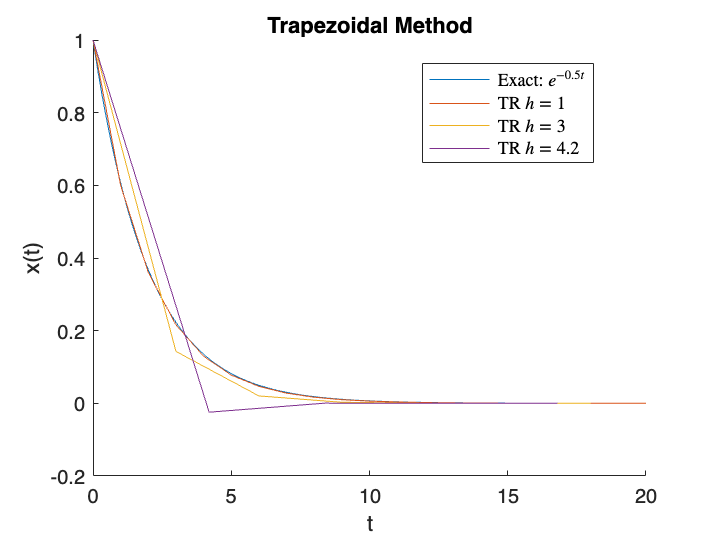

%ODE: dx/dt = -0.5 x
f  = @(t,x) -0.5*x;
x0 = 1;
t0 = 0; 
tEnd = 20;

hValues = [1, 3, 4.2];

figure;
hold on;

tFine = linspace(t0, tEnd, 1000);
plot(tFine, exp(-0.5*tFine));

%Trapezoidal for each h
for h = hValues
    t = t0:h:tEnd;
    
    x = odeTrapezoid(f, x0, t);
    plot(t, x);
end

legend("Exact: $e^{-0.5t}$", "TR $h = 1$", "TR $h = 3$", "TR $h = 4.2$", "Location", "best", "interpreter", "latex");
xlabel("t");
ylabel("x(t)");
title("Trapezoidal Method");
hold off;